# **QIBC analysis**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'U2OS DMSO',[2],2:3,1:25,[0 0 0]; %1    
        'U2OS DOX',[2],4:11,1:25,[0 0 0]; %1    


    };


load([dataDir 'D124_IFdata.mat'],'dat');



**Compare histograms **

conds = [1 2];

yval = 'allDNA';

gateVals = {'allDNA'};
rangeVals = {[18 21]}; 
data = {};

for i = 1:length(conds)
    condition = conds(i);
    ydata = (dat(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = dat(condition).(gateVals{gate})<rangeVals{gate}(2) & dat(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

figure('Units', 'Inches', 'Position', [0, 0, 4, 2])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','xlabel','log2[DNA content (RFU)]','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


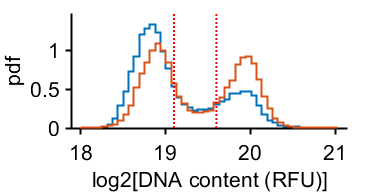

% axis square
vline([19.1 19.6])
% pbaspect([2.5 1 1])
% vline([ 6.75 10])
print_pdf([pwd() '\Figs\DNAhists.pdf'])


data

data = 1×2 cell array
    {27456×1 double}    {22718×1 double}


**Compare histograms **

data = {};
yval = 'allFarRed1';

conds = [1];
gateVals = {'allDNA'};
rangeVals = {[0 19.1]}; 
for i = 1:length(conds)
    condition = conds(i);
    ydata = (dat(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = dat(condition).(gateVals{gate})<rangeVals{gate}(2) & dat(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

conds = [1 2];
gateVals = {'allDNA'};
rangeVals = {[19.1 19.6]}; 
for i = 1:length(conds)
    condition = conds(i);
    ydata = (dat(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = dat(condition).(gateVals{gate})<rangeVals{gate}(2) & dat(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

figure('Units', 'Inches', 'Position', [0, 0, 4, 2])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(3))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','xlabel','log2[Cyclin A (RFU)]','FontSize',16)

ans = 1×3 cell array
    {'Plot #1: '}    {'Plot #2: 1 points counted in the rightmost bin are greater than 11.81 , '}    {'Plot #3: '}


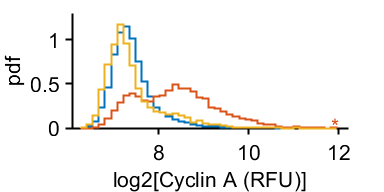

% axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
% vline([ 6.75 10])
print_pdf([pwd() '\Figs\CCNAhists.pdf'])


data

data = 1×3 cell array
    {16855×1 double}    {3983×1 double}    {3138×1 double}


**Check  stain**

numcells = 27456

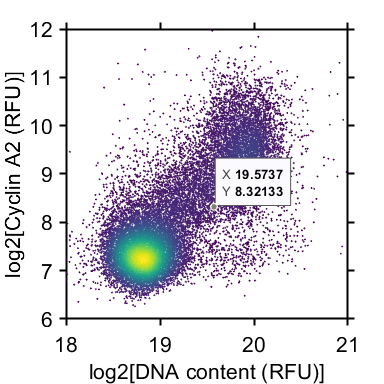

numcells = 22718

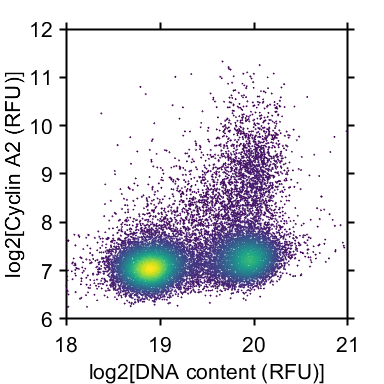

conds=[1:2];
xval = 'allDNA';
yval = 'allFarRed1';

xlimits = [18 21];
ylimits = [ 6 12];

for i = 1:length(conds)
    condition = conds(i);
    xdata = (dat(condition).(xval));
    ydata =  real((dat(condition).(yval)));
    inds = xdata < xlimits(2) & xdata > xlimits(1) & ydata > ylimits(1) & ydata < ylimits(2);
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim(xlimits);
    ylim(ylimits);
    ylabel('log2[Cyclin A2 (RFU)]');
    xlabel('log2[DNA content (RFU)]');
%     title(conditions{condition,1});
    colormap viridis
    box on
    numcells = length(xdata)
 print_pdf([pwd() '\Figs\dnavsA2_' num2str(i) '.pdf'])
end